## Spatial Filtering

1.Read img1.png and convert it to a grayscale image.

imc1 = imread("img1.png");
img1 = rgb2gray(imc1);

2.Perform the spatial filtering operations using self-defined spatial filter function. add zero padding around the image.

   The implementation is encapsulated in function sfilter().

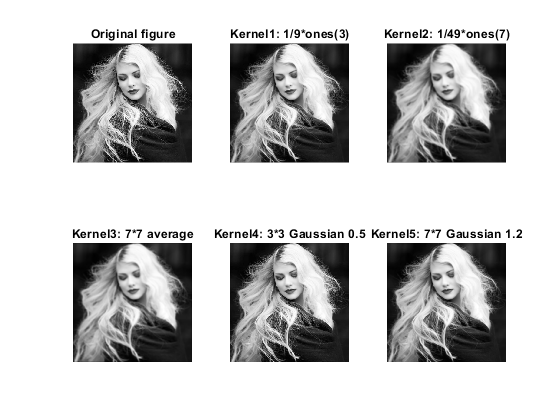

s(1).kernel = 1/9*ones(3);
s(2).kernel = 1/49*ones(7);
s(3).kernel = fspecial('average', [7,7]);
s(4).kernel = fspecial('gaussian', [3,3], 0.5);
s(5).kernel = fspecial('gaussian', [7,7], 1.2);
imgtitle = {'Kernel1: 1/9*ones(3)', 'Kernel2: 1/49*ones(7)',...
    'Kernel3: 7*7 average','Kernel4: 3*3 Gaussian 0.5', 'Kernel5: 7*7 Gaussian 1.2',...
    'Kernel6', 'Kernel7', 'Kernel8: log3'};

figure('Name', 'Normal Spatial Filter')
subplot(2,3,1);
imshow(img1);
title('Original figure');
for i = 1:5
    fimg1 = sfilter(s(i).kernel, img1);
    subplot(2,3,i+1);
    imshow(fimg1,[]);
    title(imgtitle{i});
end

3. performs median filtering using self-defined median filter function. add zero padding around the image.

    The implementation is encapsulated in function mfilter().

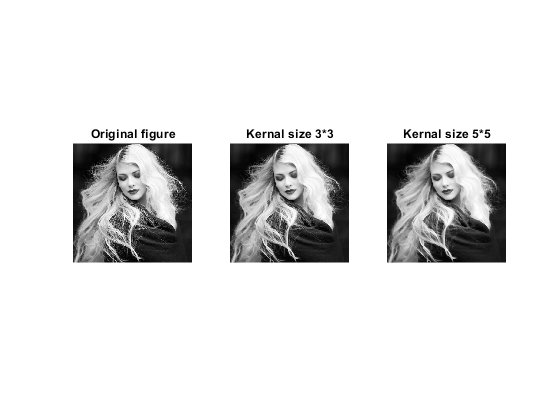

figure('Name', 'Median Filter');
subplot(1,3,1);
imshow(img1);
title('Original figure');
mimg1 = mfilter(3,3,img1);
mimg2 = mfilter(5,5,img1);
subplot(1,3,2);
imshow(mimg1, []);
title('Kernal size 3*3');
subplot(1,3,3);
imshow(mimg2, []);
title('Kernal size 5*5');

4. Read img2.png and convert it into a grayscale image. 

    Apply new kernels, which are used to enhance the edges in images.

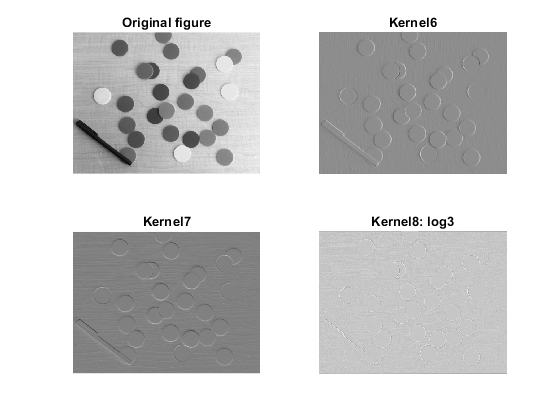

imc2 = imread("img2.png");
img2 = rgb2gray(imc2);
s(6).kernel = [-1,0,1;-2,0,2;-1,0,1];
s(7).kernel = [-1,-2,-1;0,0,0;1,2,1];
s(8).kernel = fspecial('log',3);

figure('Name', 'Enhance the edges')
subplot(2,2,1);
imshow(img2);
title('Original figure');
for i = 6:8
    fimg2 = sfilter(s(i).kernel, img2);
    subplot(2,2,i-4);
    imshow(fimg2,[]);
    title(imgtitle{i});
end

## Thresholding

1.Read the images and convert them into a grayscale images. 

imc3 = imread("img3.png");
img3 = rgb2gray(imc3);
imc4 = imread('img4.png');

img4 = rgb2gray(imc4);

2. Implement Ostu's Method to determine the appropriate threshold value of an image.

    The expression of class probabilities $\omega$, class means $\mu$ and inter-class variance $\sigma$ are:


$$\begin{array}{l}
\omega_{0}(t)=\sum_{i=0}^{t-1} p(i) \quad
\omega_{1}(t)=\sum_{i=t}^{L-1} p(i)\\
\mu_0(t) =\frac{ \sum_{i=0}^{t-1}ip(i)}{\omega_0(t)}\quad
\mu_1(t) =\frac{\sum_{i=t}^{L-1} ip(i)}{\omega_1(t)}
\end{array}
$$



$$
\sigma_{b}^{2}(t) =\omega_{0}(t) \omega_{1}(t)\left[\mu_{0}(t)-\mu_{1}(t)\right]^{2}$$


    However, it's not easy to compute $\mu_1 \left(t\right)$. We use the following relations:


$$\mu_T =\sum_{i=0}^{L-1} ip(i)$$



$$\begin{array}{l}
\omega_0 \mu_0 +\omega_1 \mu_1 =\mu_T \\
\omega_0 +\omega_1 =1
\end{array}$$
    

    Thus, we can only calculate $\omega_0 \;$, $\mu_1$and $\mu_T$. And the expression of $\sigma_{b}^{2}(t)$ can be simplified as:


$$\sigma_{b}^{2}(t) = \frac{(\mu_0-\mu_T)^2\omega_0}{\omega_1}$$


    The implementation is encapsulated in function ostu().

    3. Calculate and report the threshold values for im3.png and im4.png

T3 = otsu(img3)

T3 = 177

T4 = otsu(img4)

T4 = 129

    4.Develop code to convert a grayscale image to a binary image using a given threshold value. 

        since it's simple, we don't build a new function.

    5.Use the threshold values found and generate binary image for img3.png and img4.png.

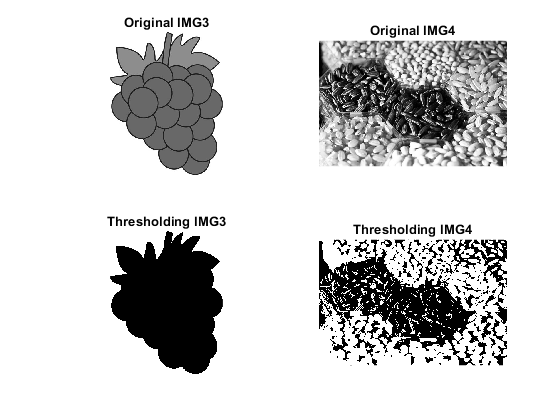

imb3 = ( img3 > T3);
imb4 = ( img4 > T4);

figure('Name', 'Thresholding');
subplot(2,2,1);
imshow(img3);
title('Original IMG3');
subplot(2,2,2);
imshow(img4);
title('Original IMG4');
subplot(2,2,3);
imshow(imb3);
title('Thresholding IMG3');
subplot(2,2,4);
imshow(imb4);
title('Thresholding IMG4');

## Discussion

1. Compare the smoothing effects obtained by Kernel 1 to Kernel 5 and the median filters.

    Kernel 1, kernel 4, and median filter with kernel size 3*3 have a slight overall blurring of the image. Only small 

size features lost, for example, the hair silk.

    Kernel 5 and median filter with kernel size 7*7 resulte in more pronounced blurring throughout the image.

    Kernel 2 and Kernel 3 have the most significant blurring of all components of the image, including the loss 

of the characteristic shape of some components, including, for example, most of the hair. 

2. Discuss the effect the kernel size has on the output images in your experiments.

All of these filters have same trend: the bigger kernel size,  more pronounced blurring throughout the image.

3. Compare the outputs obtained by Kernel 6 to Kernel 8.

Kernel 6 and Kernel 7 have similar effect, while Kernel 7 has more pronounced edges and is a little bit darker.

Kernel 8 provides a lighter image,which makes edges less significant.

4. Discuss the effect noise has on edge detection.

 In an image, edges represents a swift change in the intensity, and noise also performs the same pattern. The noise

may not have significant change as edges, and its size is much smaller than edges. If we use smoothing spatial filter, 

the noise won't have more pronounced effect. But if we use sharpening spatial filter, when enhance the edges, the 

noise will also be enhanced. 

5. Global thresholding can fail if the lighting conditions in an image are not uniform. Review

adaptive thresholding and explain how it can address uneven lighting conditions.

Adaptive Thresholding:  Thresholding T depends on the spatial coordinates (x, y) themselves.

illumination has huge influence on histogram. It corrupts the deep valley between peaks in histogram.

adaptive thresholding can have multiple thresholdings to deal with the corrupted deep valley. 